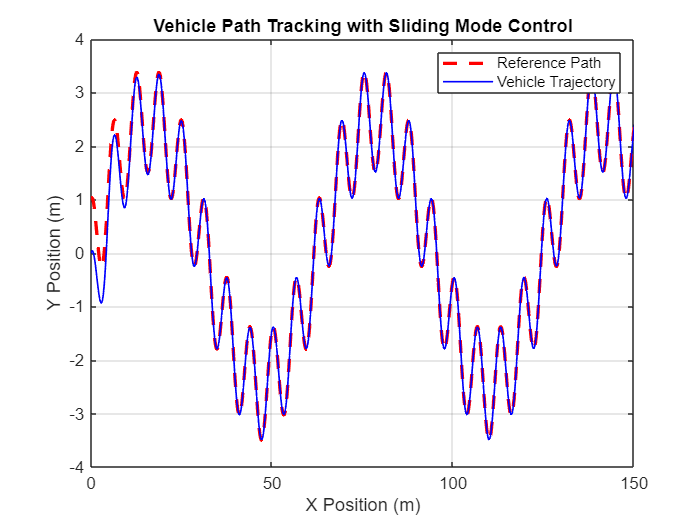

% Parameters
v = 5;                 % Vehicle speed (m/s)
K = 10;                % SMC gain
theta = 0.1;           % Smoothing parameter
lambda = 2;            % Sliding surface parameter
A = 2.5;                 % Amplitude of sinusoidal path
k = 0.1;               % Frequency of sinusoidal path
t_end = 45;            % Simulation time (s)

% Reference Path
x_ref = linspace(0, v*t_end, 1000);
y_ref = A * sin(k * x_ref) + cos(x_ref);

% Vehicle Dynamics Function
vehicle_dynamics = @(t, state) dynamics_smc(t, state, x_ref, y_ref, v, K, theta, lambda);

% Initial Conditions [x, y, psi]
state0 = [0, 0, 0];

% Solve the System
[t, state] = ode45(vehicle_dynamics, [0 t_end], state0);

% Extract Results
x = state(:,1);
y = state(:,2);

% Plot Results
figure;
plot(x_ref, y_ref, 'r--', 'LineWidth', 2); hold on;
plot(x, y, 'b', 'LineWidth', 1);
title('Vehicle Path Tracking with Sliding Mode Control');
xlabel('X Position (m)');
ylabel('Y Position (m)');
legend('Reference Path', 'Vehicle Trajectory');
grid on;

xlim([0, 150])
ylim([-4 4])


% Vehicle Dynamics Function Definition
function dstate = dynamics_smc(t, state, x_ref, y_ref, v, K, theta, lambda)
    % Unpack State Variables
    x = state(1);
    y = state(2);
    psi = state(3);
    
    % Interpolate Reference Path
    y_desired = interp1(x_ref, y_ref, x, 'linear', 'extrap');
    dy_desired = interp1(x_ref, gradient(y_ref, x_ref), x, 'linear', 'extrap');
    
    % Compute Lateral Error and Sliding Surface
    ey = y - y_desired;
    dot_ey = v * sin(psi) - v * dy_desired / sqrt(1 + dy_desired^2);
    s = ey + lambda * dot_ey;
    
    % SMC Control Law
    gamma = -K * tanh(s / theta);
    
    % Vehicle Dynamics
    dx = v * cos(psi);
    dy = v * sin(psi);
    dpsi = gamma;
    
    % State Derivative
    dstate = [dx; dy; dpsi];
end
